# Observer Design Exercises

## Exercise 1

Consider the same satelite system from last exercise session, as sketched in Figure 1.

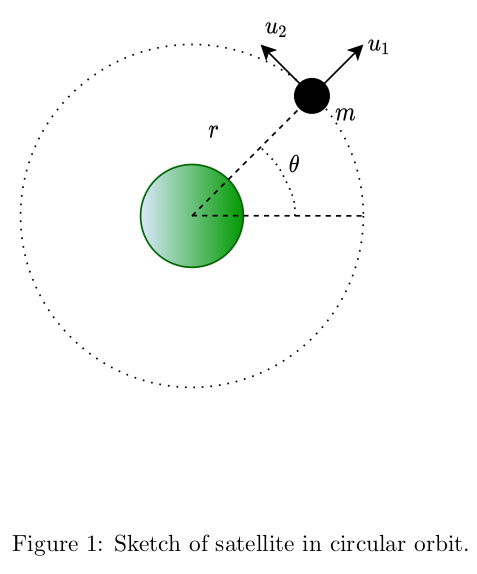

The satelite is of mass $m$ with thrust in the radial direction $u_1$ and in the tangential direction direction $u_2$. The states and inputs are given by


$$x=\left\lbrack \begin{array}{c}
r\\
\theta \\
\dot{r} \\
\dot{\theta} 
\end{array}\right\rbrack ,\;\;\;\;\;\;\;\;u=\left\lbrack \begin{array}{c}
u_1 \\
u_2 
\end{array}\right\rbrack$$


Linearized in the operating point $\bar{x} =\left(\bar{r} ,\bar{\theta} ,0,\bar{\dot{\theta} } \right)$, the linear state space system is given by


$$\dot{x} =\left\lbrack \begin{array}{cccc}
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1\\
2\;{\bar{\dot{\theta} } }^2  & 0 & 0 & 2\;\bar{r} \bar{\dot{\theta} } \\
0 & 0 & -2\;\frac{\bar{\dot{\theta} } }{\bar{r} } & 0
\end{array}\right\rbrack x+\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0\\
\frac{1}{m} & 0\\
0 & \frac{1}{\left(m\bar{r} \right)}
\end{array}\right\rbrack u$$


The output is given by


$$y=C\;x$$


Where we need to design the output matrix $C$, Hence the following exercises:

### 1. Can we estimate all states of the satelite by measuring only $r$?

En order to be able to estimate the states, we can verify if $\left(A|C\right)$ is observable. This entails that $\mathrm{Rank}\left(A|C\right)=\mathrm{Rank}\left\lbrack A^* |C^* \right\rbrack =n$

If we only measure $r$ then by $y=C\;x$ 


$$C=\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0
\end{array}\right\rbrack$$


thus


$$r=C\;x$$


First we set the values we are linearizing about, namely the operating point.

r_bar = 1;
theta_bar = 1;
r_dot_bar = 0;
theta_dot_bar = 1;

Note that $\left(A|C\right)$ is not concatenation, but it is defined as $\left(A|C\right)=\left\lbrack \begin{array}{c}
C\\
C\;A\\
\vdots \\
C\;A{\;}^{n-1} 
\end{array}\right\rbrack \in {\mathbb{R}}^{\mathrm{pn}\times n}$

C = [1 0 0 0];
A = [0 0 1 0;
     0 0 0 1;
     2*theta_dot_bar^2 0 0 2 * r_bar*theta_dot_bar;
     0 0 -2*theta_dot_bar/r_bar 0];
obs = [C; C*A; C*A^2; C*A^3;]

obs =      1     0     0     0
     0     0     1     0
     2     0     0     2
     0     0    -2     0


rank(obs)

ans = 3

I can use observability to compute $\left(A|C\right)$

obsv(A,C)

ans =      1     0     0     0
     0     0     1     0
     2     0     0     2
     0     0    -2     0


rank(obsv(A,C))

ans = 3

This gives the same result, so i can use that from this point forward. 

Because $\mathrm{Rank}\left(A|C\right)\not= n$, the system is not observable, and we can therefore not estimate all states by measuring only $r$.

### 2. Can we estimate all states of the satellite by measuring only $\dot{\theta}$?

Since $x=\left\lbrack \begin{array}{c}
r\\
\theta \\
\dot{r} \\
\dot{\theta} 
\end{array}\right\rbrack$, then $y=\dot{\theta} =C\;x$

C = [0 0 0 1];
rank(obsv(A,C))

ans = 3

Since $\mathrm{Rank}\left(A|C\right)<n$ the system is not obersevable.

Therefore we canot estimate all states of the satellite by measuring only $\dot{\theta}$

### 3. Can we estiamte all states of the satellite by measuring both $r$ and $\dot{\theta}$?

C = [1 0 0 1];
rank(obsv(A,C))

ans = 2

Since $\textrm{Rank}\left(A|C\right)<n$ the system is not obersevable.

Therefore we canot estimate all states of the satellite by measuring $r$ and $\dot{\theta}$.

### 4. What does it take for us to be able to estimate all states?

Since $y=\mathrm{Cx}$ and $\dot{x} =A\;x+B\;u$

then $\dot{y} =C\dot{\;x} =C\left(\mathrm{Ax}+B\;u\right)$

Therefore we need to measure at least $r$ and $\theta$ to be able to estimate $\dot{r}$ and $\dot{\theta}$.

## Exercise 2

clear all

Consider the system 


$$\dot{x} =\left\lbrack \begin{array}{cc}
-5 & -4\\
1 & -5
\end{array}\right\rbrack x+\left\lbrack \begin{array}{c}
2\\
3
\end{array}\right\rbrack u$$



$$y=\left\lbrack \begin{array}{cc}
1 & 0
\end{array}\right\rbrack$$


### 1. Is the system controllable and observable?

By the duality principle we have that if $\left(A,C\right)\;$is observable then $\left(A^* ,C^* \right)$is reachable/controllable and viceversa. However for this system, in order to check controllability, then $\left(A,B\right)$ should be controllable, i.e. $\mathrm{Rank}\left\lbrack A|B\right\rbrack =n$

A = [-5 -4;
     1 -5];
B = [2;
     3];
C = [1 0];

Then we can verify observability

obs = obsv(A,C);
if rank(obs) == size(obs, 2)
    disp('(A,C) is observable');
else
    disp('(A,C) is not observable');
end

(A,C) is observable


Whic indeed has full rank, therefore the system is observable.

Let $\left\lbrack A|B\right\rbrack =\left\lbrack \begin{array}{cccc}
B & A\;B & \cdots  & A^{n-1} B
\end{array}\right\rbrack \in {\mathbb{R}}^{n\times n\;m}$

contr = [B A*B A^2*B A^3*B]

contr =      2   -22   162  -982
     3   -13    43   -53


if rank(contr) == size(contr, 2)
    disp('(A,B) is controllable');
else
    disp('(A,B) is not controllable');
end

(A,B) is not controllable


### 2. Design a feedback control law that places poles at {-1, -2}.

We have the poles

p = [-1 -2];

Because $u=K\;x$ then 

K = -place(A,B,p)

K =     0.9500    1.7000


For fun, we can check for stability.

if eig(A+B*K) < 0
    disp('The system A+B*K is stable')
else
     disp('The system A+B*K is not stable')
end

The system A+B*K is stable


### 3. Design a full order observer for the system placing the observer poles at $\left\lbrace -6,-9\right\rbrace$

An observer takes in the input $u$ and the output of the plant $y$ of the system, and it can then estimate $\hat{x}$ which is estimates of the states.


$$O=A\;\hat{x} +B\;u+L\left(y-\hat{y} \right)$$



$$\hat{y} =C\;\hat{x}$$


We can look at the error of the estimated states $\hat{x}$ with respect to the acutal states $x$


$$e=x-\hat{x}$$


We can then compute the time derivative of this error:


$$\dot{e} =\dot{x} -\dot{\hat{x} } =A\;x+B\;u-\left(A\;\hat{x} +B\;u+L\left(y-\hat{y} \right)\right)$$


and by collecting terms:


$$\dot{e} =A\;e-L\;C\;e$$


and by factoring $e$ out


$$\dot{e} =\left(A-L\;C\right)e$$


And since we want it in the form of $A-C\;L$, thus letting $C$ be the input matrix into the observer, and $L$ be the observer gain matrix. This can be done by letting ${\left(A-L\;C\right)}^* =A^* -C^* L^*$

And we need to choose $L$ s.t. $\mathrm{Re}\left(\lambda \right)<0\;\forall \;\lambda \in \sigma \left(A^* -C^* L^* \right)$

p = [-6, -9]

p =     -6    -9


L = -place(adjoint(A),adjoint(C),p)

Error using adjoint
Matrix must be square.